# MAP estimation for the binomial distribution

It is believed that the data set

x=[13    10    10    17]; 

is binomially distributed with a value of 

n=20;

trials. However, the parameter $p$ is unknown. First we establish a maximum likelihood estimate for $p$.

pMLE=mle(x,"distribution","Binomial","NTrials",n)

pMLE = 0.6250

Construct a beta distribution prior for p. Parameterize this distribution so that $\mu=pMLE$ and $\sigma=0.2$.

mu=pMLE;    %subjective guess at expected value for p
sigma=0.2;   %subjective guess at standard deviation around the expected value for p
alpha=mu*((mu*(1-mu)/sigma^2)-1);
beta=(1-mu)*alpha/mu;
p=linspace(0,1,1000);
prior=betapdf(p,alpha,beta);

Plot the prior

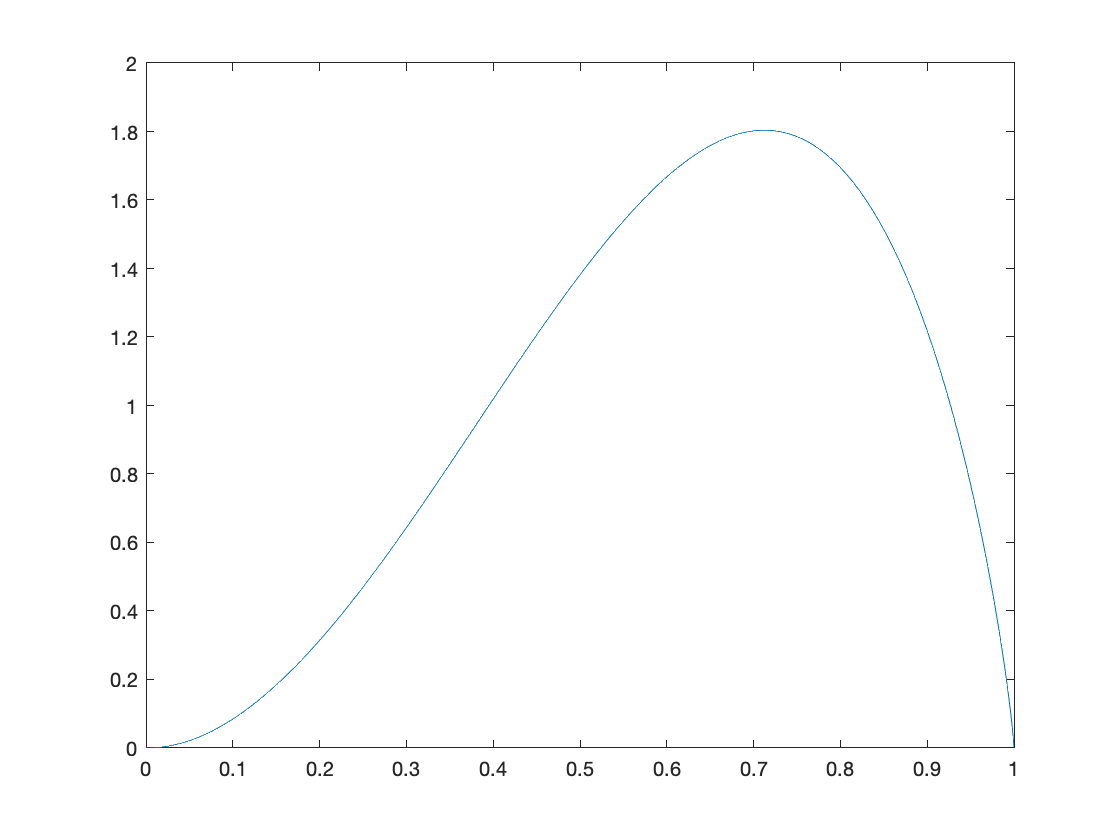

figure(2)
p1=plot(p,prior);

Construct a likelihood function for the data.

F=prod(binopdf(repmat(x',1,length(p)),repmat(n,length(x),length(p)),repmat(p,length(x),1)));

Construct the marginal probability

margin=trapz(p,F.*prior);

Construct the posterior probability and plot it

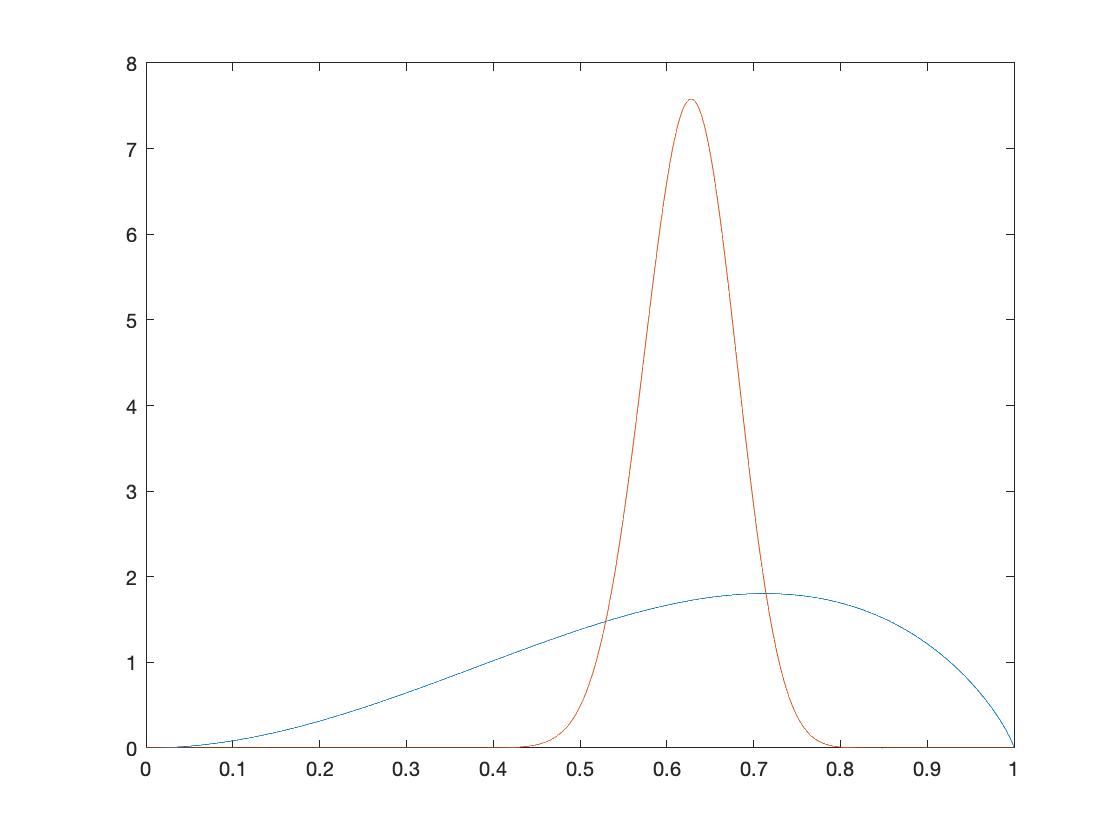

posterior=F.*prior/margin;
figure(2)
hold on
p2=plot(p,posterior);
hold off

Compute the MAP estimate for $p$ and visualize it

[M,I]=max(posterior);
MAP=p(I)

MAP = 0.6276

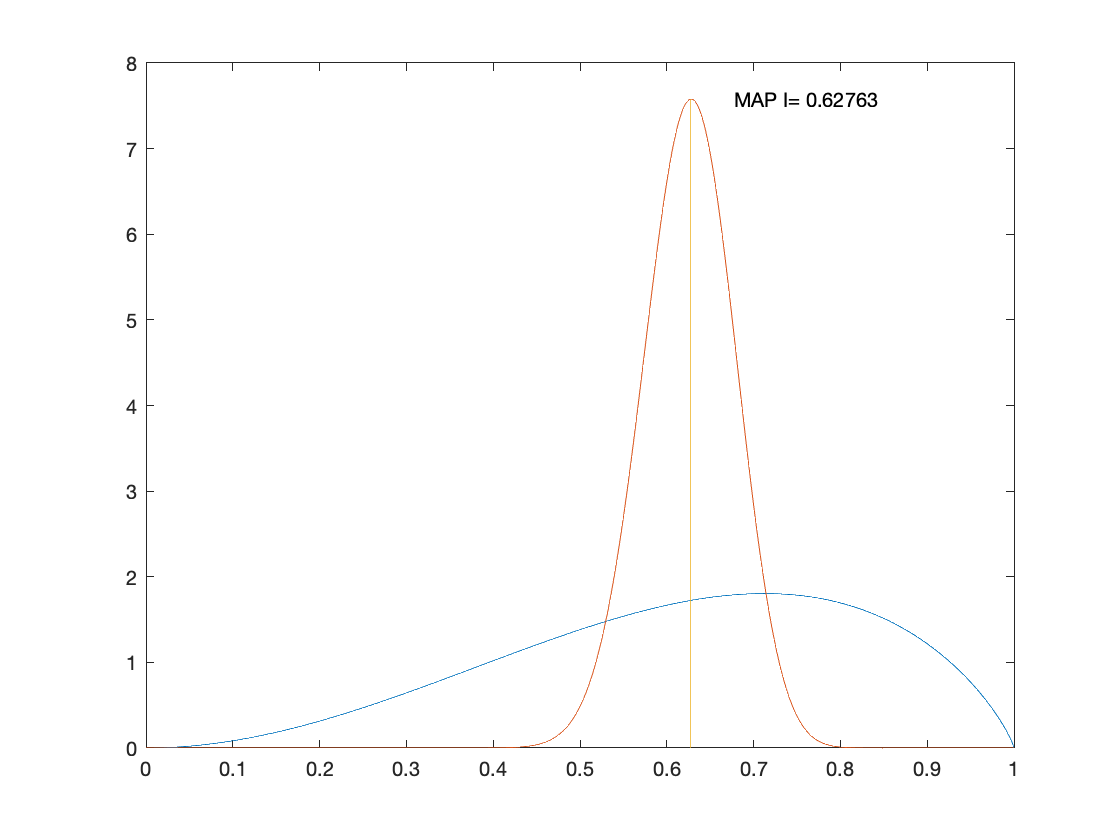

figure(2)
hold on
plot([p(I) p(I)],[0,posterior(I)]);
text(p(I)+.05,posterior(I),strjoin({'MAP I=',num2str(p(I))}))
hold off

Collect more data in order to compute an even more refined MAP estimate

x=[12    14     9    14];

Update the prior to the old posterior

prior=posterior;  

Compute a new likelihood function using the new data

F=prod(binopdf(repmat(x',1,length(p)),repmat(n,length(x),length(p)),repmat(p,length(x),1)));

Compute the new marginal probability

margin=trapz(p,F.*prior);

Compute the new posterior probability

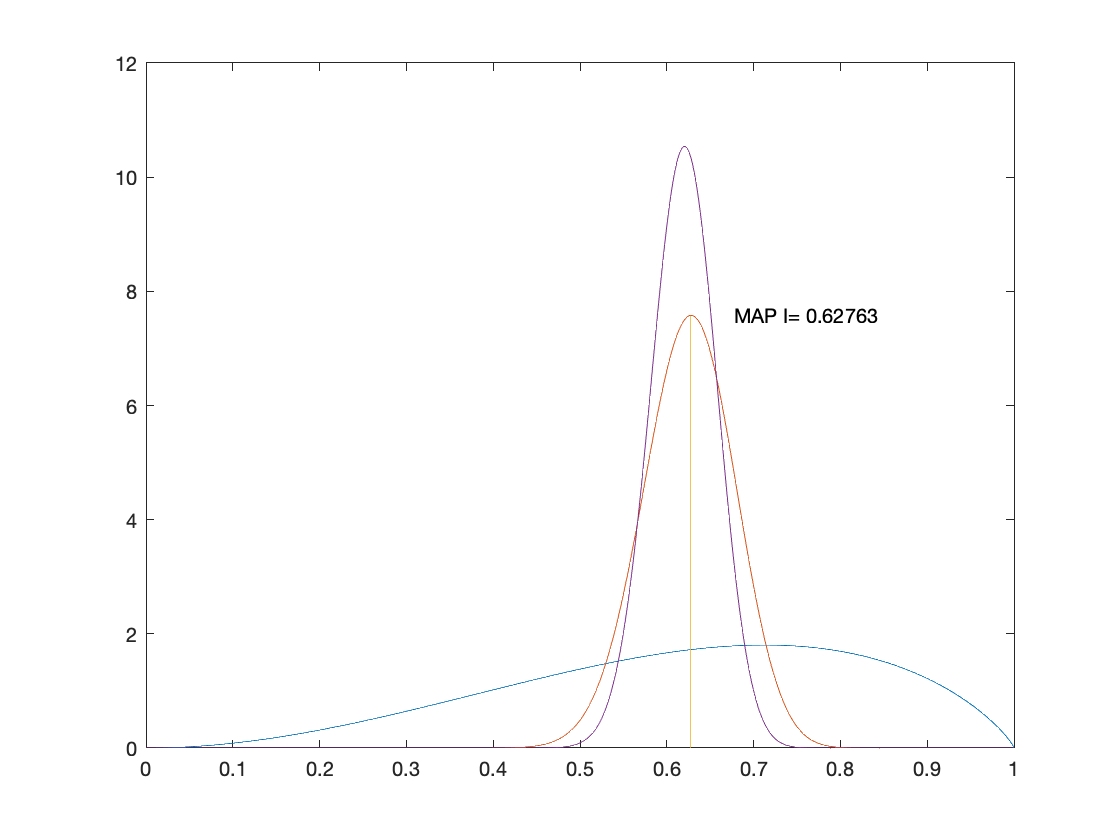

posterior=F.*prior/margin;
hold on
p3=plot(p,posterior);

Find the second, refined MAP estimate

[M,I]=max(posterior);
MAP2=p(I)

MAP2 = 0.6206

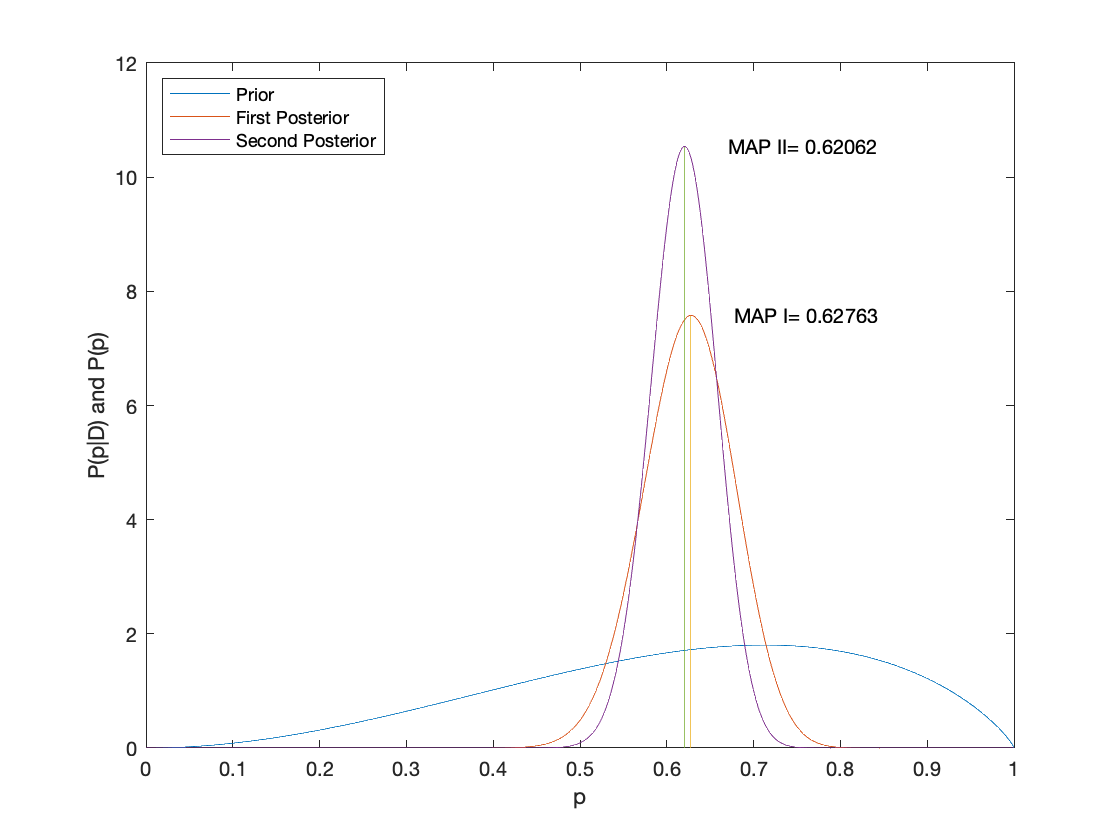

plot([p(I) p(I)],[0,posterior(I)]);
text(p(I)+.05,posterior(I),strjoin({'MAP II=',num2str(p(I))}))
legend([p1,p2,p3],'Prior','First Posterior','Second Posterior','Location','northwest')
hold off
xlabel('p')
ylabel('P(p|D) and P(p)')